## Inertia Matrix using DH generalized coordinate

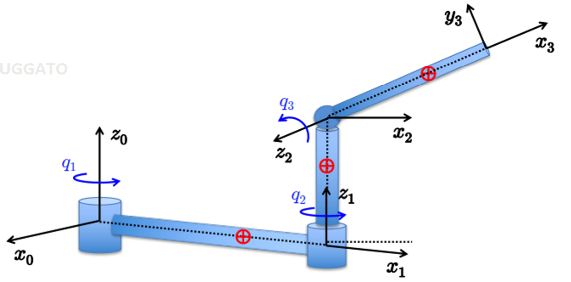ù

% Symbolic definitions
syms q1 q2 q3 dq1 dq2 dq3 real         % Joint angles and their derivatives
syms l1 l2 d3 a3 real                  % Link parameters (lengths and offsets)
syms m1 m2 m3 real                    % Masses of the links
syms I1xx I2yy I3xx I3yy I3zz real    % Inertia components (diagonal)
syms d1c d2c d3c real                 % Distance from joint to CoM for each link

%-----------------------------------
% Link 1
%-----------------------------------


% Kinetic energy of link 1
T1 = 0.5 * I1xx * dq1^2 + 0.5 * m1 * d1^2

$$T1 = \frac{m_{1}\,{d_{1}}^{2}}{2}+\frac{\mathrm{I1xx}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$


%-----------------------------------
% Link 2
%-----------------------------------

T2_tr = 0.5*m2*(l1^2)*(dq1^2);
T2_rot = 0.5*I2yy*(dq1+dq2)^2;

% Kinetic energy of link 2
T2 = T2_tr+T2_rot;

%-----------------------------------
% Link 3
%-----------------------------------
% Angular velocity
w3 = [sin(q3)*(dq1+dq2);
      cos(q3)*(dq1+dq2);
      dq3];

% CoM position of link 3 in base frame
p3c = [l1*cos(q1) + d3*cos(q3)*cos(q1+q2);
       l1*sin(q1) + d3*cos(q3)*sin(q1+q2);
       l2*sin(q2) + d3*sin(q3);];

% Velocity of CoM using Jacobian
v3 = [-(l1*sin(q1)*dq1+d3*cos(q3)*sin(q1+q2)*(dq1+dq2)+d3*sin(q3)*cos(q1+q2)*dq3);
      (l1*cos(q1)*dq1+d3*cos(q3)*cos(q1+q2)*(dq1+dq2)-d3*sin(q3)*sin(q1+q2)*dq3);
      d3*cos(q3)*dq3;];

% Inertia matrix (diagonal)
I3 = diag([I3xx, I3yy, I3zz]);

% Kinetic energy of link 3
T3_rot = 0.5 * w3.' * I3 * w3;
T3_trans = 0.5 * m3 * (v3.' * v3);
T3 = T3_rot + T3_trans

$$T3 = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+d_{3}\,\cos\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)-d_{3}\,{\mathrm{dq}}_{3}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{3}\right)\,\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)+d_{3}\,{\mathrm{dq}}_{3}\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{3}\right)\right)}^{2}+{d_{3}}^{2}\,{{\mathrm{dq}}_{3}}^{2}\,{\cos\left(q_{3}\right)}^{2}\right)}{2}+\frac{\mathrm{I3zz}\,{{\mathrm{dq}}_{3}}^{2}}{2}+\frac{\mathrm{I3yy}\,{\cos\left(q_{3}\right)}^{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{\mathrm{I3xx}\,{\sin\left(q_{3}\right)}^{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}$$


%-----------------------------------
% Total kinetic energy
%-----------------------------------
T = simplify(T1 + T2 + T3, Steps=1000);

% Display the result
disp('Total kinetic energy T =');

Total kinetic energy T =


pretty(T)

                2           2           2     2        2    2         2   2         2   2                  2            2                   2         2          2    2           2     2    2           2
I2yy (dq1 + dq2)    I1xx dq1    I3zz dq3    d1  m1   d3  dq3  m3   dq1  l1  m2   dq1  l1  m3   I3yy cos(q3)  (dq1 + dq2)    I3xx (dq1 + dq2)  (cos(q3)  - 1)   d3  dq1  m3 cos(q3)    d3  dq2  m3 cos(q3)      2                   2         2
----------------- + --------- + --------- + ------ + ----------- + ----------- + ----------- + -------------------------- - -------------------------------- + -------------------- + -------------------- + d3  dq1 dq2 m3 cos(q3)  + d3 dq1  l1 m3 cos(q2) cos(q3) + d3 dq1 dq2 l1 m3 cos(q2) cos(q3) - d3 dq1 dq3 l1 m3 sin(q2) sin(q3)
        2               2           2          2          2             2             2                     2                               2                            2                      2




% Compute the 3×3 inertia matrix via second derivatives of T w.r.t. dq1,dq2,dq3
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M13 = diff(diff(T, dq1), dq3);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);
M23 = diff(diff(T, dq2), dq3);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);
M33 = diff(diff(T, dq3), dq3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\begin{array}{l} \left(\begin{array}{ccc} \mathrm{I1xx}+\mathrm{I2yy}-\sigma_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+\sigma_{4}+\sigma_{2}+2\,d_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) & \sigma_{1} & -d_{3}\,l_{1}\,m_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{1} & \mathrm{I2yy}-\sigma_{3}+\sigma_{4}+\sigma_{2} & 0\\ -d_{3}\,l_{1}\,m_{3}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & 0 & m_{3}\,{d_{3}}^{2}+\mathrm{I3zz} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{I2yy}-\sigma_{3}+\sigma_{4}+\sigma_{2}+d_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{2}={d_{3}}^{2}\,m_{3}\,{\cos\left(q_{3}\right)}^{2}\\ \sigma_{3}=\mathrm{I3xx}\,\left({\cos\left(q_{3}\right)}^{2}-1\right)\\ \sigma_{4}=\mathrm{I3yy}\,{\cos\left(q_{3}\right)}^{2} \end{array}$$